Example Run of Model

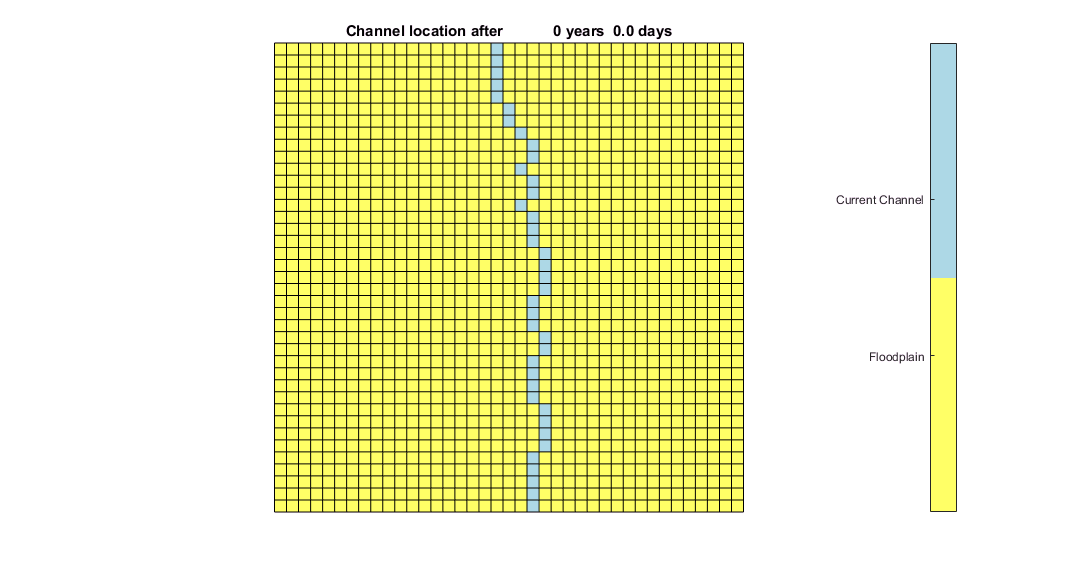

% how many meters of stratigraphy?
stratMeters = 20;

% create an instance of the class AvulsionModel
A = AvulsionModel(.5, 1/4, 0, [20,30,38,39]);

% calculate the number of time steps to run
nTimeSteps = ceil(A.timeStepsPerMeter * stratMeters);

% generate initial river channel
A.generateInitialChannel(floor(A.numCols/2));

% display 2-d domain
A.plotRiver; drawnow

Run algorithms

% display progress bar
progressBar = waitbar(0, 'Running Avulsion Model');

counter = 1;

while A.timeElapsed < nTimeSteps
  
  % run aggradation until avulsion
  A.aggradeUntilAvulsion;
  
  % avulse to new channel
  A.avulseToNewChannel
  
  % Update status
  waitbar(A.timeElapsed/nTimeSteps);
  
  % update counter
  counter = counter+1;
  
end %while

% close progress bar
delete(progressBar);

disp('Avulsion model run completed.');

Avulsion model run completed.


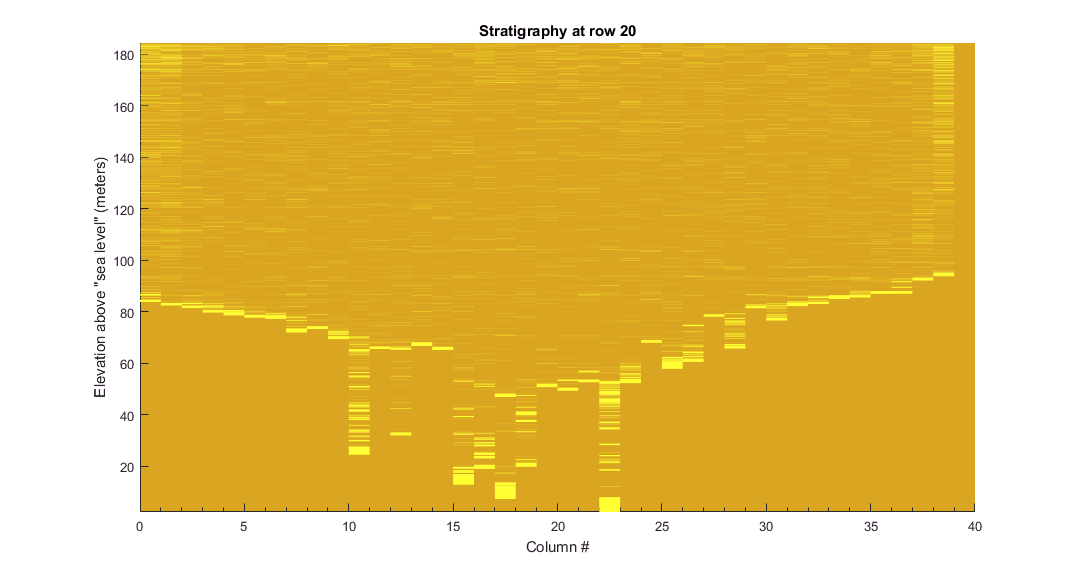

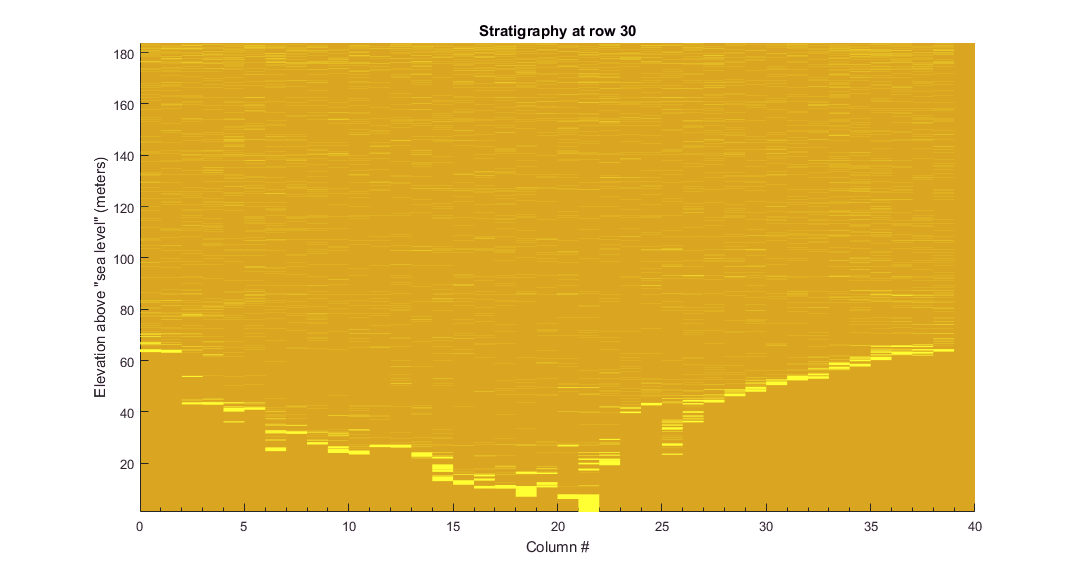

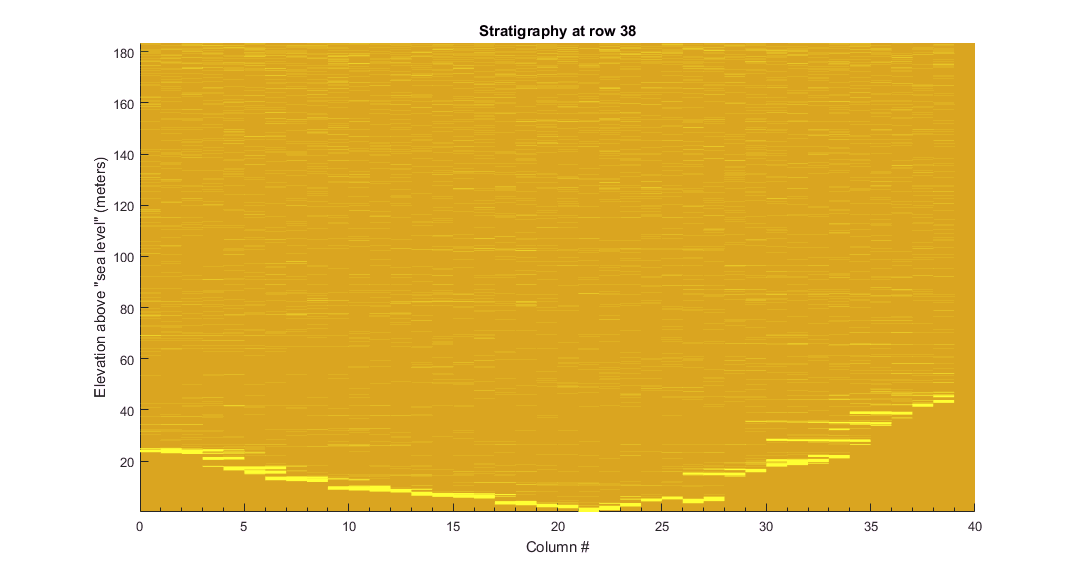

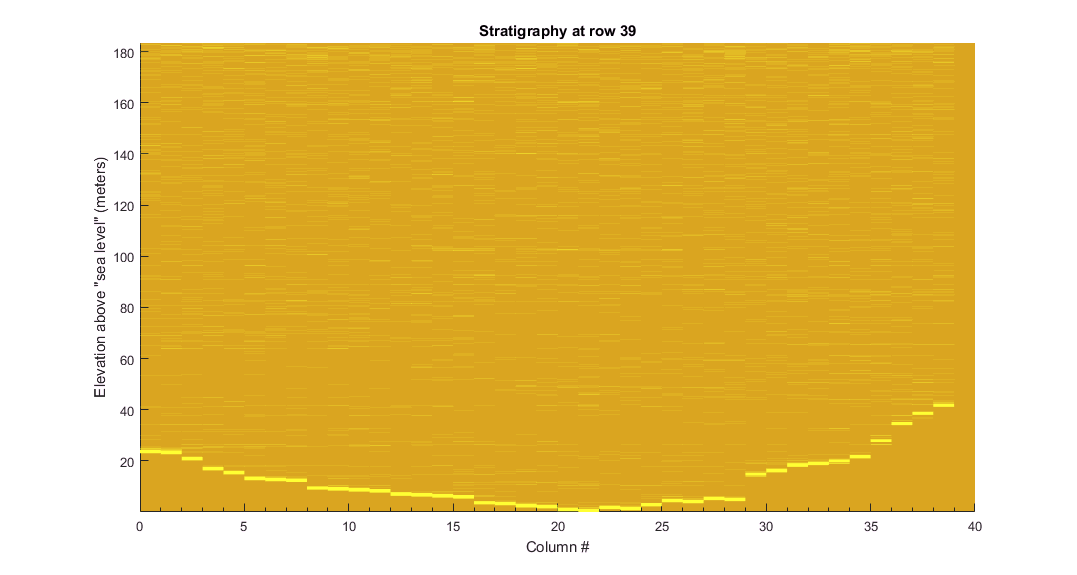

A.plotStratigraphy